% classic MATLAB script header;
clc;
clear;
close all;
dbstop if error;
format long g;
warning('off');

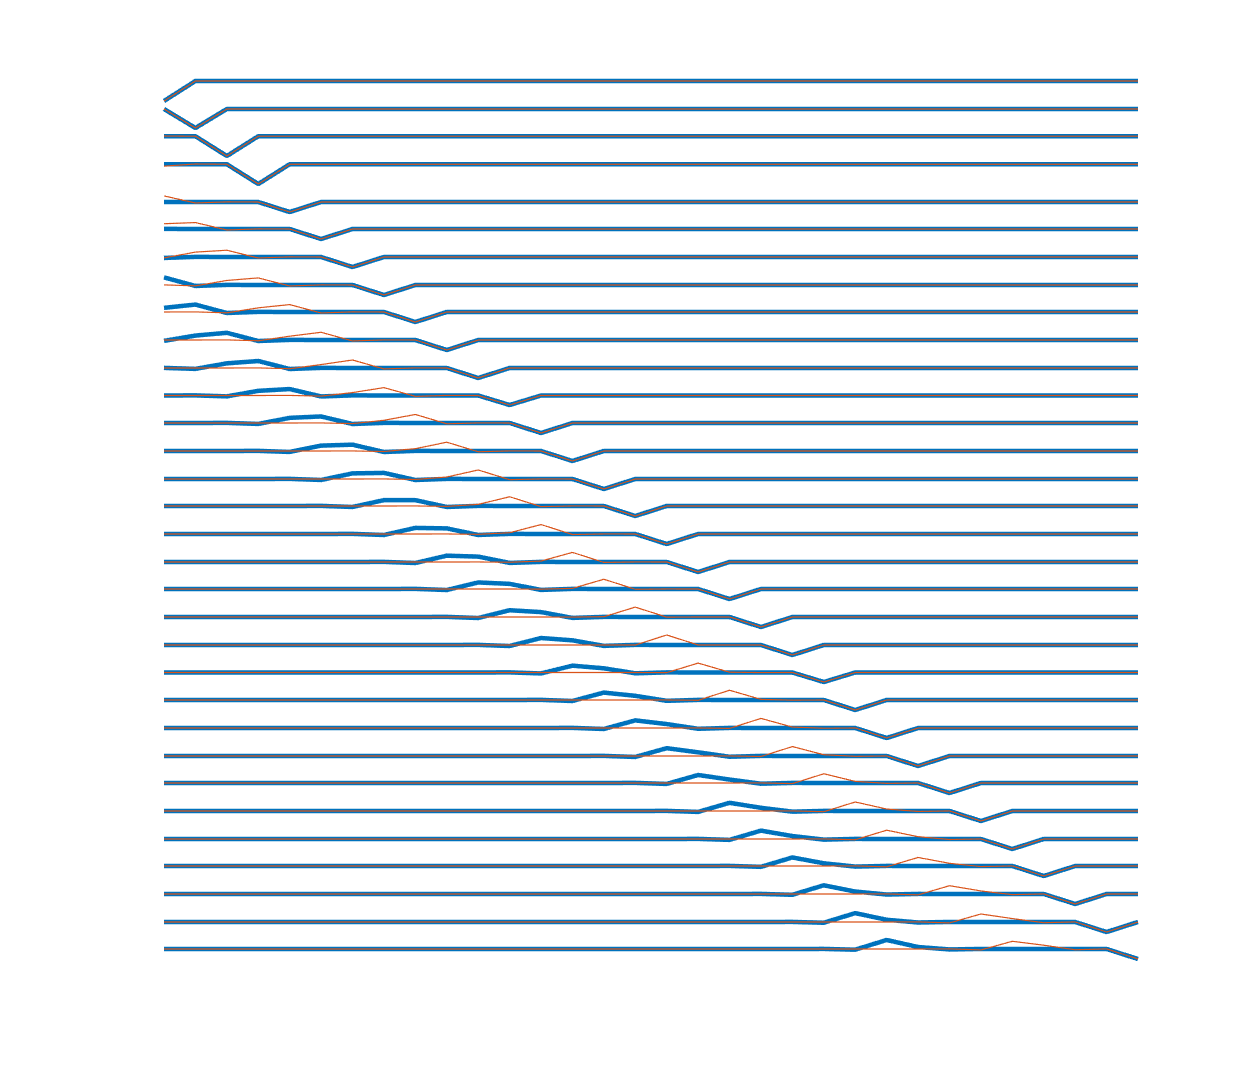

% fig-2

% time length
time_length = 31;
% length of lagrange kernel
n = 6;
% time series
t = 0: 1: time_length;
% arm-1
length1 = 6.2 + 0.02 * t;
tarrival1 = t - length1; % assume c = 1
% arm-2
length2 = 4.6 - 0.03 * t;
tarrival2 = t - length2; % assume c = 1
% design matrix
m = zeros(2 * time_length, time_length);

% construct the design matrix
for i = 1: 1: 2 * time_length + 2
    % this epoch
    m(i, ceil(i / 2)) = -1;
    % other epoch
    if (mod(i, 2) ~= 0) % for arm1
        central_epoch1 = floor(tarrival1(ceil(i / 2)));
        kernel1 = lagrange_kernel(6, tarrival1(ceil(i / 2)) - floor(tarrival1(ceil(i / 2))));
         for k = central_epoch1 - 2: 1: central_epoch1 + 3
            if k > 0
                m(i, k) = kernel1(k - central_epoch1 + 3);
            end
        end
    else % for arm2
        central_epoch2 = floor(tarrival2(ceil(i / 2)));
        kernel2 = lagrange_kernel(6, tarrival2(ceil(i / 2)) - floor(tarrival2(ceil(i / 2))));
        for k = central_epoch2 - 2: 1: central_epoch2 + 3
            if k > -1
                m(i, k + 1) = kernel2(k - central_epoch2 + 3);
            end
        end
    end
end

% plot matrix
figure('DefaultAxesFontSize', 16, 'color', [1 1 1], 'Name', 'Piston Phase Wrapped');
for i = 1: 1: time_length + 1
    % signal 1
    subplot(time_length + 1, 1, i)
    plot(t, m((i - 1) * 2 + 1, :), 'linewidth', 2.7);
    hold on;
    plot(t, m((i - 1) * 2 + 2, :), 'linewidth', 0.7);
    % grid on;
    box off;
    set(gca, 'Visible', 'off')
    set(gcf, 'Units', 'centimeters', 'Position', [10 10 70 60]);
    set(gca, 'YTickLabel', [], 'XTickLabel', []); % remove xytick
    xlim([0, time_length]);
    % xlabel('Time [s]', 'fontsize', 20); 
    % ylabel('Amplitude', 'fontsize', 20); 
    % set(gca, 'FontSize', 20, 'linewidth', 1.1);
end